## Excel I/O Functions

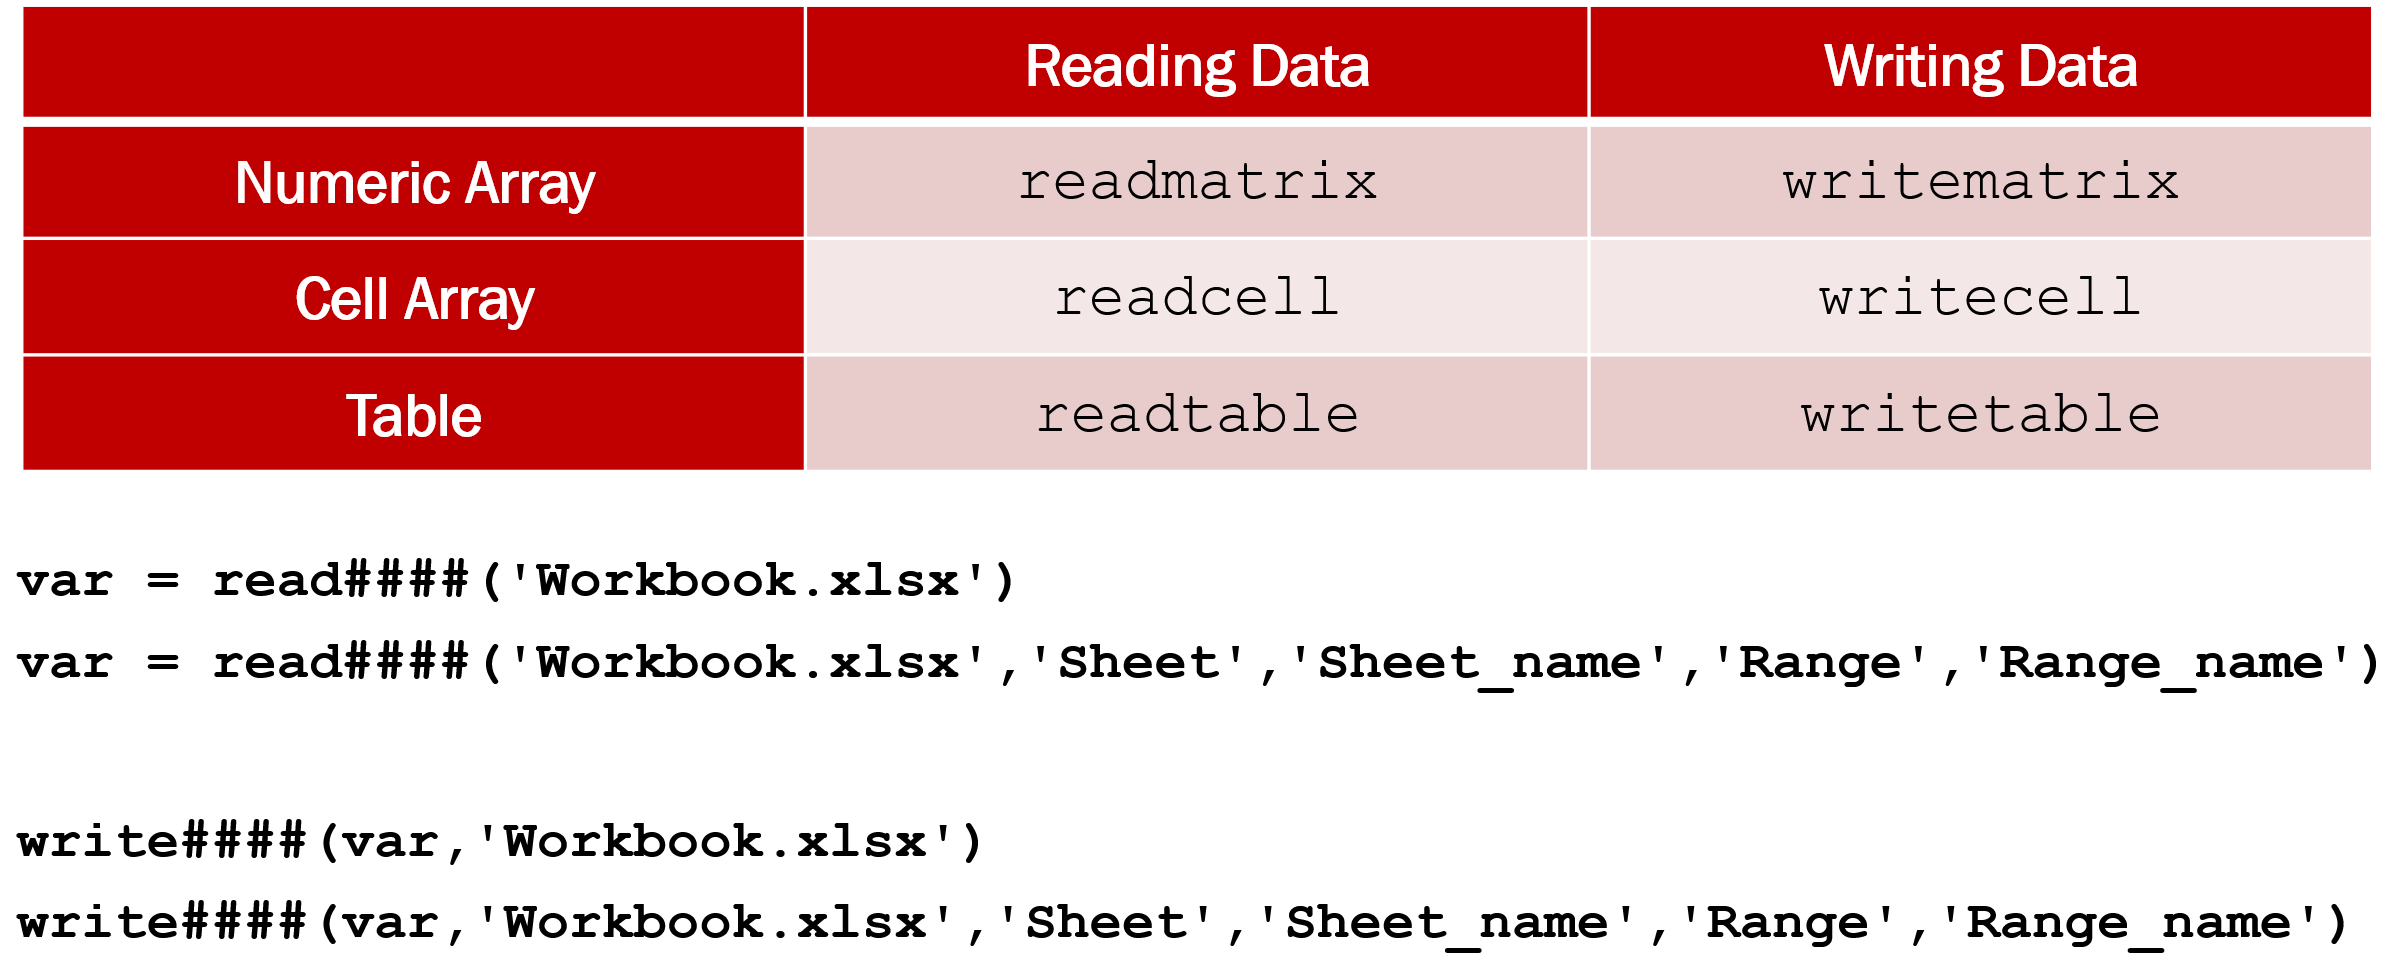

## Range Arguments

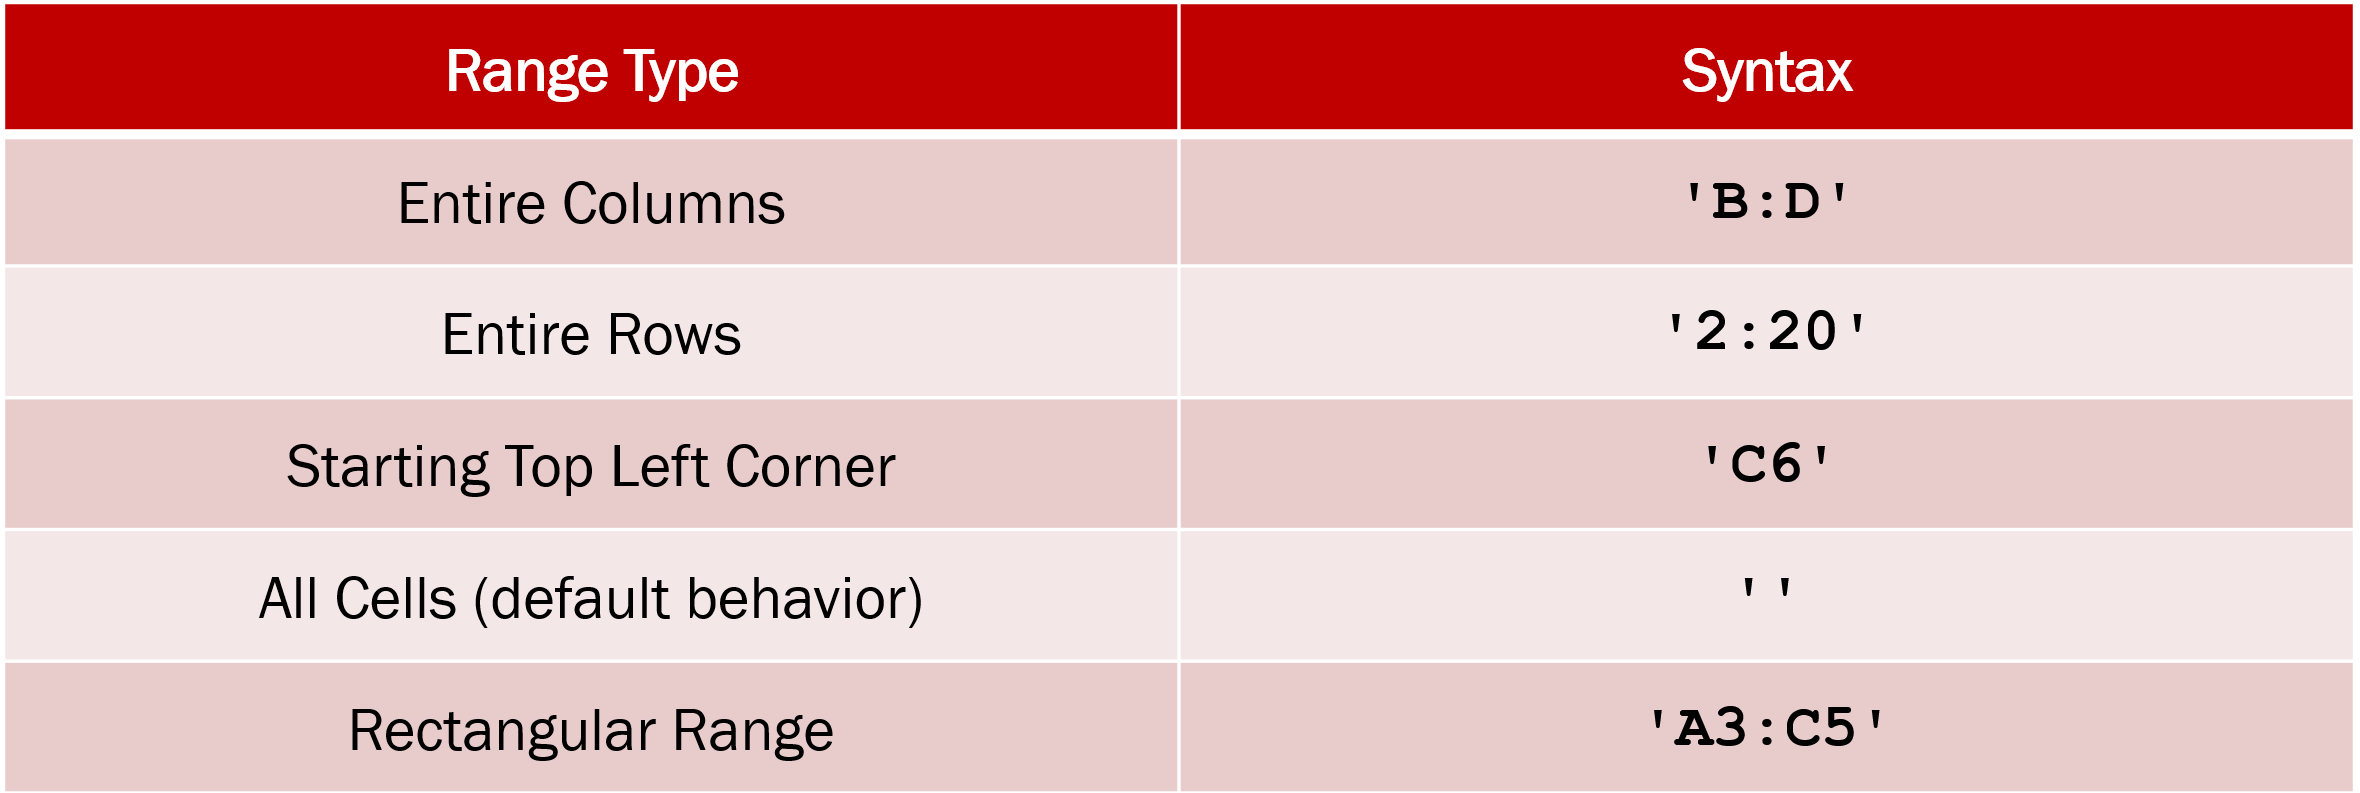

## Bottles

Download the worksheet `Bottles.xlsx`, as shown below, and save it in your MATLAB directory. The data continues beyond the rows shown.

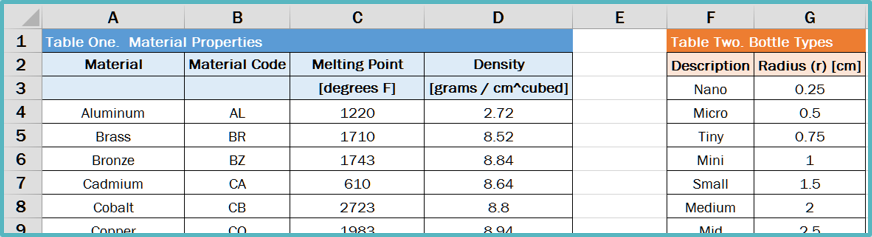

Import all the **columns** with Material Property data from the file Bottles.xlsx as a table.

A=readtable('Bottles.xlsx','Range',"A:D")

A = 20×4 table
      Material       MaterialCode    MeltingPoint    Density
    _____________    ____________    ____________    _______

    {'Aluminum' }       {'AL'}           1220          2.72 
    {'Brass'    }       {'BR'}           1710          8.52 
    {'Bronze'   }       {'BZ'}           1743          8.84 
    {'Cadmium'  }       {'CA'}            610          8.64 
    {'Cobalt'   }       {'CB'}           2723           8.8 
    {'Copper'   }       {'CO'}           1983          8.94 
    {'Gold'     }       {'GO'}           1945         19.29 
    {'Iron'     }       {'IR'}           2100          7.87 
    {'Lead'     }       {'LD'}            621         11.35 
    {'Magnesium'}       {'MG'}           1200          1.74 
    {'Nickel'   }       {'NI'}           2647           8.9 
    {'Platinum' }       {'PL'}           3220          

Sometimes the column names are not what you want. One strategy to address this to just read in just the four cells of the header row as a cell array and use these to rename the column names in the table.

*Note: Any spaces in the header titles need to be removed so they are valid variable names. The *`strrep`* (string replace) function can do this.*

A.Properties.VariableNames=strrep(readcell('Bottles.xlsx','Range',"A2:D2"),' ','_')

A = 20×4 table
      Material       Material_Code    Melting_Point    Density
    _____________    _____________    _____________    _______

    {'Aluminum' }       {'AL'}            1220           2.72 
    {'Brass'    }       {'BR'}            1710           8.52 
    {'Bronze'   }       {'BZ'}            1743           8.84 
    {'Cadmium'  }       {'CA'}             610           8.64 
    {'Cobalt'   }       {'CB'}            2723            8.8 
    {'Copper'   }       {'CO'}            1983           8.94 
    {'Gold'     }       {'GO'}            1945          19.29 
    {'Iron'     }       {'IR'}            2100           7.87 
    {'Lead'     }       {'LD'}             621          11.35 
    {'Magnesium'}       {'MG'}            1200           1.74 
    {'Nickel'   }       {'NI'}            2647            8.9 
    {'Platinum' }       {'PL'

Using the data with appropriate column names, identify which material is the least dense and save the name of that material as a character array into the variable `LightWeight`.

[min_val,min_loc]=min(A.Density)

min_val = 1.7400

min_loc = 10

LightWeight=A.Material{min_loc}

LightWeight = 'Magnesium'

## Widgets

Download the worksheet `Widgets.xlsx`, as shown below, and save it in your MATLAB directory. The data continues beyond the rows shown.

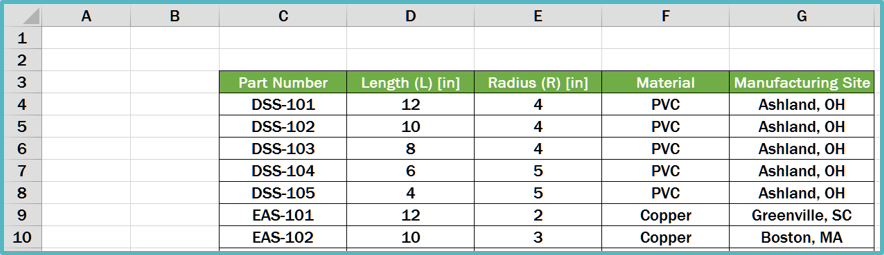

Import the Part Number column as a **cell array**, including the header, from the file `Widgets.xlsx`.

Import the length and radius columns as a **matrix**, from the file `Widgets.xlsx`.

Assume each part imported is a cylinder.  Determine the volume of each part in units of cubic inches.

C=readcell('Widgets.xlsx','Range','C:C')

C = 21×1 cell array
    {'Part Number'}
    {'DSS-101'    }
    {'DSS-102'    }
    {'DSS-103'    }
    {'DSS-104'    }
    {'DSS-105'    }
    {'EAS-101'    }
    {'EAS-102'    }
    {'EAS-103'    }
    {'EAS-104'    }
    {'EAS-105'    }
    {'JBS-101'    }
    {'JBS-102'    }
    {'JBS-103'    }
    {'JBS-104'    }
    {'JBS-105'    }
    {'KAS-101'    }
    {'KAS-102'    }
    {'KAS-103'    }
    {'KAS-104'    }
    {'KAS-105'    }


D=readmatrix('Widgets.xlsx','Range','D:E')

D =    NaN   NaN
    12     4
    10     4
     8     4
     6     5
     4     5
    12     2
    10     3
     8     5
     6     4


E=pi*D(2:end,2).^2.*D(2:end,1)

E =   603.1858
  502.6548
  402.1239
  471.2389
  314.1593
  150.7964
  282.7433
  628.3185
  301.5929
  113.0973


Write the MATLAB code segment necessary to write the part number and volume data to the Excel file.  The data should write to a new worksheet in the `Widgets` file, containing the part name and the corresponding volume.  

Your worksheet should contain appropriate data column headings.

writecell(C,'Widgets.xlsx','Sheet','New_Sheet')

Error using writecell
Unable to write to file 'C:\Users\ellag\OneDrive\Desktop\MatLab\Widgets.xlsx'.  You may not have write permissions or the file may be open by another application.

writematrix(E,'Widgets.xlsx','Sheet','New_Sheet','Range','B:B')

## Part Info

Download the worksheet `Part Info.xlsx`, as shown below, and save it in your MATLAB directory. The data continues beyond the rows shown.

Import all data in the worksheet as a table, from the file `Part Info.xlsx`**.**

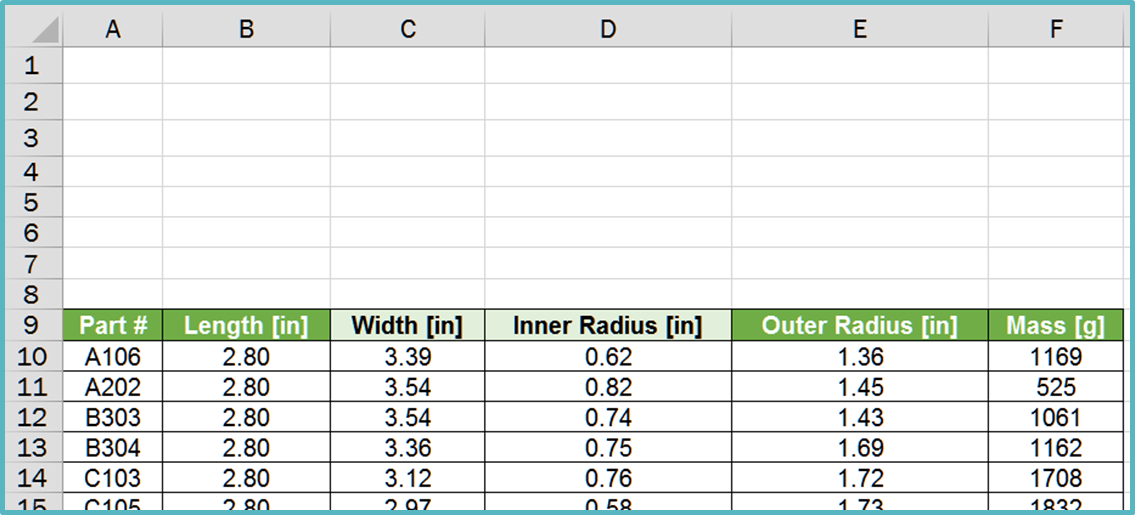

bro=readtable('Part Info.xlsx')

bro = 78×6 table
     Part_      Length_in_    Width_in_    InnerRadius_in_    OuterRadius_in_    Mass_g_
    ________    __________    _________    _______________    _______________    _______

    {'A106'}        2.8         3.39            0.615              1.356         1169.3 
    {'A202'}        2.8         3.54           0.8175              1.452         524.84 
    {'B303'}        2.8         3.54            0.735              1.428         1061.1 
    {'B304'}        2.8         3.36             0.75              1.692         1161.7 
    {'C103'}        2.8         3.12           0.7575              1.716         1708.3 
    {'C105'}        2.8         2.97           0.5775              1.728         1832.5 
    {'C201'}        2.8         3.54             0.66             

Determine the volume of the part, in cubic inches, assuming all parts are a solid cylinder.

Determine the specific gravity of each part.

Volume=bro.OuterRadius_in_.^2*2*pi.*bro.Length_in_

Volume =    32.3487
   37.0912
   35.8752
   50.3661
   51.8051
   52.5322
   56.2436
   42.1580
   33.0398
   29.2635


rho_w=1 %g/cm^3

rho_w = 1

SG=bro.Mass_g_./Volume/rho_w/(2.54^3) %[]

SG =     2.2058
    0.8635
    1.8049
    1.4075
    2.0122
    2.1287
    0.9503
    1.3258
    1.3190
    1.5593


Write the MATLAB code segment necessary to write the part number, volume, and specific gravity data to the Excel file.  The data should write to a new worksheet in the `Part Info `file.  

Your worksheet should contain appropriate data column headings.

T2=table(bro.Part_,Volume,SG)

T2 = 78×3 table
      Var1       Var2      Var3  
    ________    ______    _______

    {'A106'}    32.349     2.2058
    {'A202'}    37.091    0.86348
    {'B303'}    35.875     1.8049
    {'B304'}    50.366     1.4075
    {'C103'}    51.805     2.0122
    {'C105'}    52.532     2.1287
    {'C201'}    56.244    0.95025
    {'A107'}    42.158     1.3258
    {'C306'}     33.04      1.319
    {'A308'}    29.264     1.5593
    {'C106'}    43.715     1.3999
    {'A103'}    28.351     1.6916
    {'C305'}    66.475     1.2235
    {'A306'}    35.581     1.1795
    {'B106'}    55.177     1.7039
    {'B206'}    29.601    0.76396


writetable(T2,'Part Info.xlsx','Sheet','New')

Unable to write to file 'C:\Users\ellag\OneDrive\Desktop\MatLab\Part Info.xlsx'.  You may not have write permissions or the file may be open by another application.

writecell({'Part Number','Volume','Specific Gravity'},'Part Info.xlsx','Sheet','New')